## Reading netlist

Read the netlist obtainded from the simulator and request frequency and step frequcency.

NOTE: Adding the Z value (only the numeric value) to the table migth not be useful at this point, since a swipe of frequecies will need to be implemented therefore modifiying the Z value for each element.

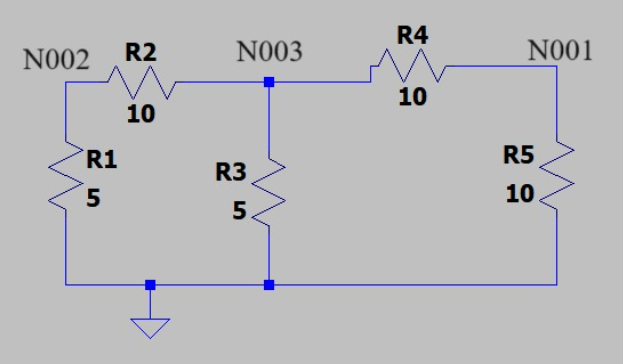

%MAIN PROGRAM
clear all
netlist_file = 'CircuitoPrueba1.net'

netlist_file = 'CircuitoPrueba1.net'

%netlist_file = 'CircuitoT.net' %has C & L
f=20E3;

%WIP: Develop a top function that calls all sub-functions in a loop per frequency steps
NodesTable = Netlist2table(netlist_file, f)

'sip2num' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\monts\OneDrive\Documentos\Escuela\Cinvestav\Primer Cuatrimestre\RFI\Proyecto

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in proyecto_v0>Netlist2table (

Gmatrix = gen_Gmatrix(NodesTable, f)

## Generating the MNA matrices

There are three matrices we need to generate, the **A** matrix, the **x** matrix and the **z** matrix.

### The A matrix

The **A** matrix will be developed as the combination of 4 smaller matrices, [**G**](https://lpsa.swarthmore.edu/Systems/Electrical/mna/MNA3.html#G_matrix), [**B**](https://lpsa.swarthmore.edu/Systems/Electrical/mna/MNA3.html#B_matrix), [**C**](https://lpsa.swarthmore.edu/Systems/Electrical/mna/MNA3.html#C_matrix), and [**D**](https://lpsa.swarthmore.edu/Systems/Electrical/mna/MNA3.html#D_matrix).  

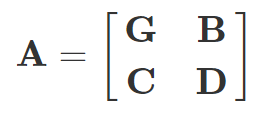

The **A** matrix is (*m*+*n*)×(*m*+*n*) (*n* is the number of nodes, and *m* is the number of independent voltage sources) and:

- the **G** matrix is *n*×*n* and is determined by the interconnections between the passive circuit elements (resistors)

- the **B** matrix is *n*×*m* and is determined by the connection of the voltage sources.

- the **C** matrix is *m*×*n* and is determined by the connection of the voltage sources. ( **B** and **C** are closely related, particularly when only independent sources are considered).

- the **D** matrix is *m*×*m* and is zero if only independent sources are considered.

function NodesTable = Netlist2table(netlist_file, freq)
fileID= fopen(netlist_file,'r','n','UTF-8');

n=1;
while(~feof(fileID))
    nline = fgetl(fileID);
    if(~contains(nline,'.') && ~contains(nline,'*')) 
       splitted_nline = strsplit(nline);
       NumVal= sip2num(splitted_nline{:,4});
       
       %calculate impedance of the element and add it to the table
       elem_Type = splitted_nline{:,1};
       elem_Type = elem_Type(1,1);
       ZVal = calcZval(elem_Type, NumVal, freq);

       NodesTable(n,:) = [splitted_nline, {elem_Type}, {NumVal}, {ZVal}]; 
       n=n+1;
    end
end
end

function ZVal = calcZval(elem_Type, NumVal, freq)
w=2*pi*freq;
switch elem_Type
            case 'R'
                ZVal=NumVal; 
            case 'C' % Zc = 1/-jwc
                ZVal=1i/(w*NumVal);
            case 'L' % Zl = jwL
                ZVal=1i*w*NumVal;
            case 'V'
                ZVal=NumVal;
       end
end

function Gmatrix = gen_Gmatrix(NodesTable, freq)
w=2*pi*freq;

%calculate the number of nodes for the Gmatrix size
nodesC2 = NodesTable(:,2); %elements start nodes
nodesC3 = NodesTable(:,3); %elements end nodes
allNodesConn = [nodesC2; nodesC3];
allNodes = unique(allNodesConn,'sorted');
nodesNum = length(allNodes)-1; %Remove the reference node
Gmatrix = zeros(nodesNum,nodesNum);

%Process to fill the Gmatrix
%Note that reference node is assumed to be always '0'.
for  i=1:size(NodesTable,1)

    nodeC2 = nodesC2{i};
    nodeNum_n = regexp(nodeC2,'\d*','Match');
    nodeNum_n = str2double(nodeNum_n{:});

    nodeC3 = nodesC3{i};
    nodeNum_m = regexp(nodeC3,'\d*','Match');
    nodeNum_m = str2double(nodeNum_m{:});

    %Main diagonal: elements connecting to node n (G11, G22, ...)
    if(contains(nodeC2,'N') && ~contains(NodesTable{i,1},'V')) %exclude reference node and Vnode
        ZVal = calcZval(NodesTable{i,5}, NodesTable{i,6}, freq);
        Gmatrix(nodeNum_n,nodeNum_n)=(1/ZVal)+Gmatrix(nodeNum_n,nodeNum_n);
    end

    if(contains(nodeC3,'N') && ~contains(NodesTable{i,1},'V')) %exclude reference node and Vnode
        ZVal = calcZval(NodesTable{i,5}, NodesTable{i,6}, freq);
        Gmatrix(nodeNum_m,nodeNum_m)=(1/ZVal)+Gmatrix(nodeNum_m,nodeNum_m);
    end

    %Secondary diagonals: elements between nodes (not reference node, G12, G21, ...)
    if(contains(nodeC2,'N') && contains(nodeC3,'N') && ~contains(NodesTable{i,1},'V')) 
        ZVal = calcZval(NodesTable{i,5}, NodesTable{i,6}, freq);
        Gmatrix(nodeNum_n,nodeNum_m)=-(1/ZVal)+Gmatrix(nodeNum_n,nodeNum_m);
        Gmatrix(nodeNum_m,nodeNum_n)=-(1/ZVal)+Gmatrix(nodeNum_m,nodeNum_n);
    end
    
end
end
